UNIVERSIDADE FEDERAL DO PIAUÍ - UFPI

CENTRO DE TECNOLOGIA

DISCIPLINA: ELETRÔNICA DE POTÊNCIA

DOCENTE: RAFAEL ROCHA 

DISCENTE: MARIANA DE SOUSA MOURA

# CURVA CARACTERÍSTICA DO DUTY CYCLE D 

Desenvolveu-se as curvas características do Duty Cycle D em função da relação de corrente da carga (Io/Io.max) dos conversores Buck, Boost e Buck-Boost. Os pontos de intersecção entre as curvas (alternância entre os modos de condução) são determinados igualando-se as equações dos modos de condução. Igualou-se as equações para os modos de condução contínua e descontínua, substitui-se os valores de m (correspondente a Vo/E) dados e obteve-se os intervalos.

Em todos os gráficos, o valor de Vo foi considerado constante e observou-se o comportamento das curvas para os diferentes modos de operação dos conversores. 

## Gráfico de ganho para o conversor Buck

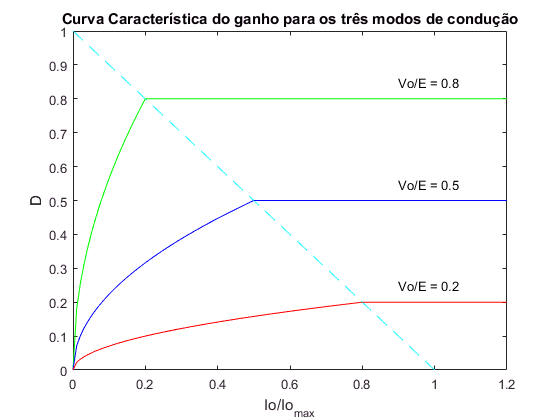

% Gráfico de ganho do conversor Buck
clc
clear all
close all
figure (1);
% MODO DESCONTÍNUO
% m = V0/Vd;
% n = I0/Ilb_max;
n = 0:0.01:0.2;
m = 0.8;
D = m*sqrt(n/(1-m));
plot(n,D,'g');
hold on
m = 0.5;
n = 0:0.01:0.5;
D = m*sqrt(n/(1-m));
plot(n,D,'b');
hold on
m = 0.2;
n = 0:0.01:0.8;
D = m*sqrt(n/(1-m));
plot(n,D,'r');
hold on


% MODO FRONTEIRA
g = 0:0.01:1;
D = 1 - g;
plot(g,D,'--c');
hold on


% MODO CONTÍNUO
g = 0.2:0.01:1.2;
for i= 1:101
m(i) = 0.8;
D(i) = m(i);
end
plot(g,D,'g');

hold on
clear('g','D');
g = 0.5:0.01:1.2;
for i= 1:71
m(i) = 0.5;
D(i) = m(i);
end
plot(g,D,'b');

hold on
clear('g','D');
g = 0.8:0.01:1.2;
for i= 1:41
m(i) = 0.2;
D(i) = m(i);
end
plot(g,D,'r');

title('Curva Característica do ganho para os três modos de condução');
xlabel('Io/Io_{max}')
ylabel('D')
text(0.9,0.85,'Vo/E = 0.8');
text(0.9,0.55,'Vo/E = 0.5');
text(0.9,0.25,'Vo/E = 0.2');

## Gráfico de ganho para o conversor Boost

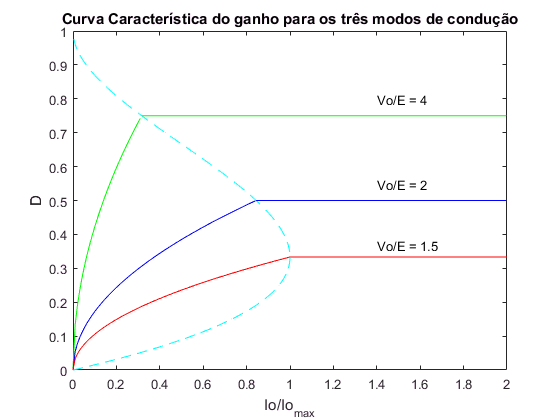

% CONVERSOR BOOST
clear all
figure (2);
% MODO DESCONTÍNUO
n = 0:0.01:81/256;
m = 4;
D = sqrt((4/27)*m*(m-1)*n);
plot(n,D,'g');
hold on

clear('D','m','n');
n = 0:0.01:27/32;
m = 2;
D = sqrt((4/27)*m*(m-1)*n);
plot(n,D,'b');

hold on
clear('D','m','n');
n = 0:0.01:1;
m = 1.5;
D = sqrt((4/27)*m*(m-1)*n);
plot(n,D,'r');
hold on

% MODO DE FRONTEIRA
clear('D');
D = 0:0.01:0.99;
for i = 1:100
mm(i) = (27/4)*D(i)*(1-D(i)).^2;
end
plot(mm,D,'--c');
hold on

%% MODO CONTÍNUO
clear('D','m','g');
g = 81/256:0.01:2;
for i= 1:169
m(i) = 4;
D(i) = 1 - (1/m(i));
end
plot(g,D,'g');
hold on
clear('D','m','g');
g = 27/32:0.01:2;
for i= 1:116
m(i) = 2;
D(i) = 1 - (1/m(i));
end
plot(g,D,'b');
hold on
clear('D','m','b');
g = 1:0.01:2;
for i= 1:101
m(i) = 1.5;
D(i) = 1 - (1/m(i));
end
plot(g,D,'r');

title('Curva Característica do ganho para os três modos de condução');
xlabel('Io/Io_{max}')
ylabel('D')
text(1.4,0.8,'Vo/E = 4');
text(1.4,0.55,'Vo/E = 2');
text(1.4,0.37,'Vo/E = 1.5');

## Gráfico de ganho para o conversor Buck-Boost

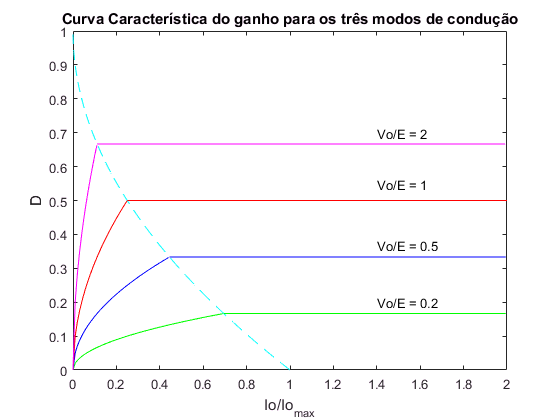

% CONVERSOR BUCK-BOOST
clear all

% MODO DESCONTÍNUO
n = 0:0.01:25/36;
m = 0.2;
figure(3);
for i= 1:70
D(i) = m/sqrt(1/n(i));
end
plot(n,D,'g');

hold on
clear('D','m','n');
n = 0:0.01:4/9;
m = 0.5;
for i= 1:45
D(i) = m/sqrt(1/n(i));
end
plot(n,D,'b');
hold on

clear('D','m','n');
n = 0:0.01:1/4;
m = 1;
for i= 1:26
D(i) = m/sqrt(1/n(i));
end
plot(n,D,'r');

hold on
clear('D','m','n');
n = 0:0.01:1/9;
m = 2;
for i= 1:12
D(i) = m/sqrt(1/n(i));
end
plot(n,D,'m');
hold on

% MODO FRONTEIRA
clear('D','n');
D = 0:0.01:0.99;
for i = 1:100
mm(i) = (1-D(i)).^2;
end
plot(mm,D,'--c');
hold on

%% MODO CONTÍNUO
clear('D','m','g');
g = 25/36:0.01:2;
for i= 1:131
m(i) = 0.2;
D(i) = m(i)/(1+m(i));
end
plot(g,D,'g');
hold on
clear('D','m','g');
g = 4/9:0.01:2;
for i= 1:156
m(i) = 0.5;
D(i) = m(i)/(1+m(i));
end
plot(g,D,'b');
hold on
clear('D','m','g');
g = 1/4:0.01:2;
for i= 1:176
m(i) = 1;
D(i) = m(i)/(1+m(i));
end
plot(g,D,'r');

hold on
clear('D','m','g');
g = 1/9:0.01:2;
for i= 1:189
m(i) = 2;
D(i) = m(i)/(1+m(i));
end
plot(g,D,'m');

title('Curva Característica do ganho para os três modos de condução');
xlabel('Io/Io_{max}')
ylabel('D')
text(1.4,0.7,'Vo/E = 2');
text(1.4,0.55,'Vo/E = 1');
text(1.4,0.37,'Vo/E = 0.5');
text(1.4,0.2,'Vo/E = 0.2');